# Exercici 6 de Laboratori

Binaritzat i segmentació

(Per Francesc Forn, Raúl Lumbreras i Martí Vall)

L’objectiu de la sessió és fer una petita aplicació per a la captura i contrast de documents utilitzant el mòbil,  en escenaris on la il·luminació no està gaire controlada. 

**1. **Primer obtenir una imatge amb el vostre mòbil d’una pàgina amb diverses línies de text d’imprenta, situat sobre un fons més o menys homogeni i més fosc que el paper. 

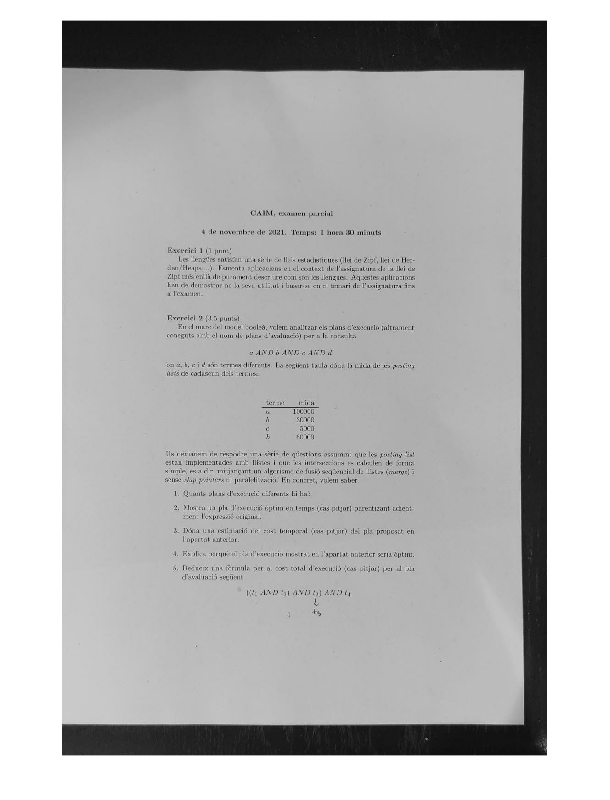

I = rgb2gray((imread("img.jpg")));
imshow(I);

**2.** Realitzeu una binarització global del document de tal manera que el full quedi binaritzat a blanc i el que no és el full a negre. Un primer procediment que us proposem per a binaritzar globalment el document seria buscar el llindar de binarització que deixi el 80%, o més, de la imatge binaritzada a blanc.  Podeu utilitzar altres estratègies de binarització i comparar resultats. 

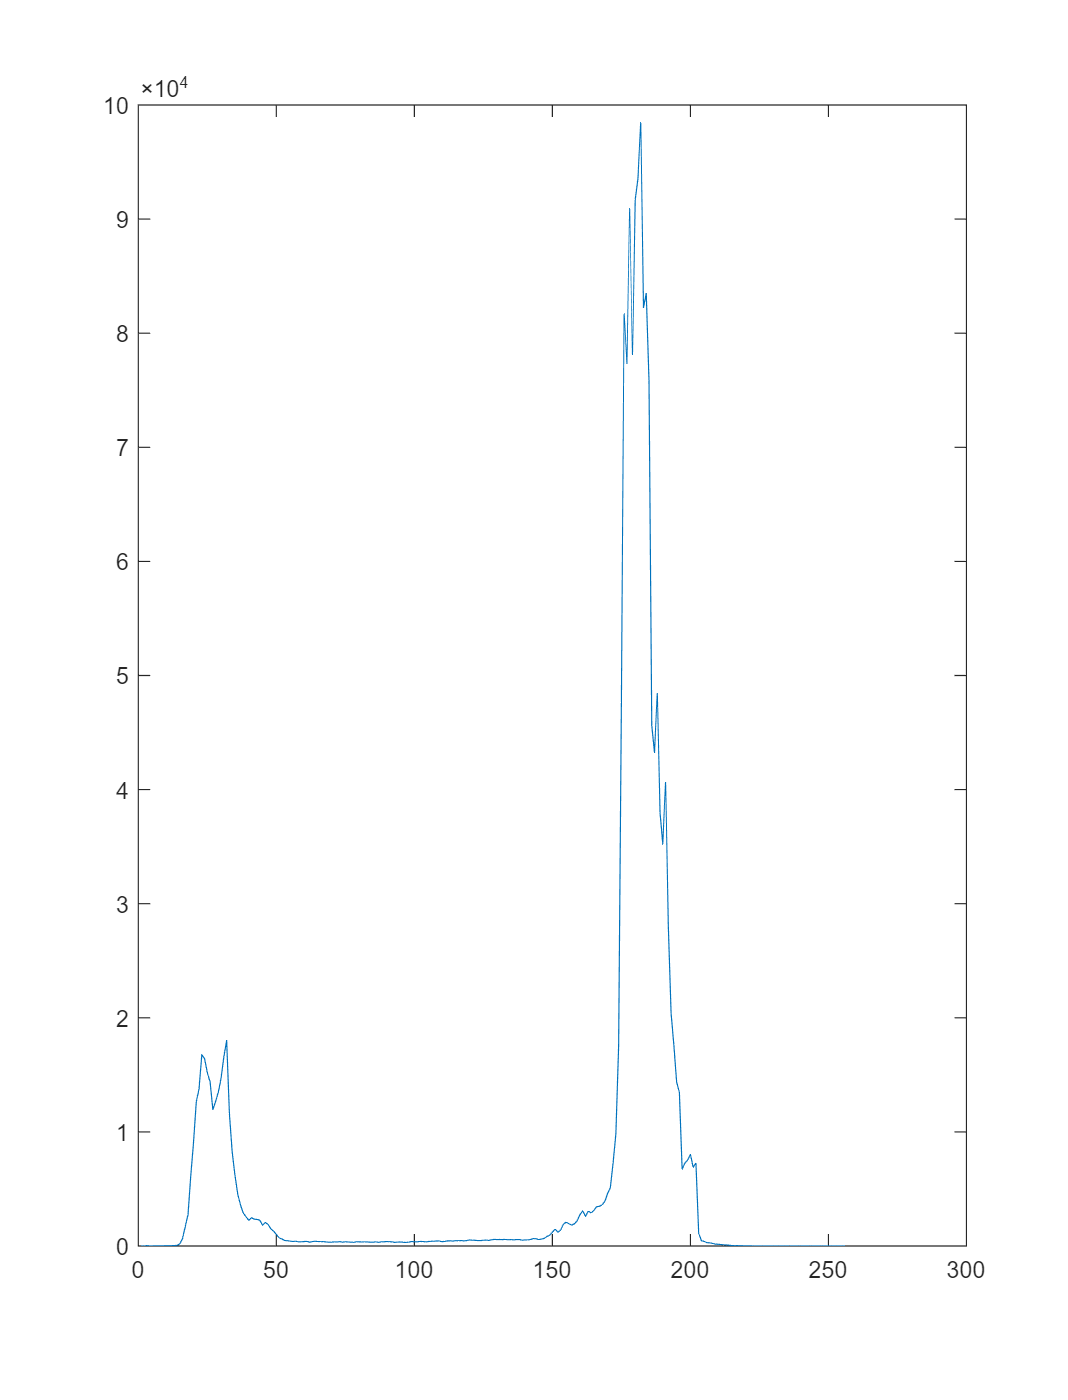

h = imhist(I); plot(h);

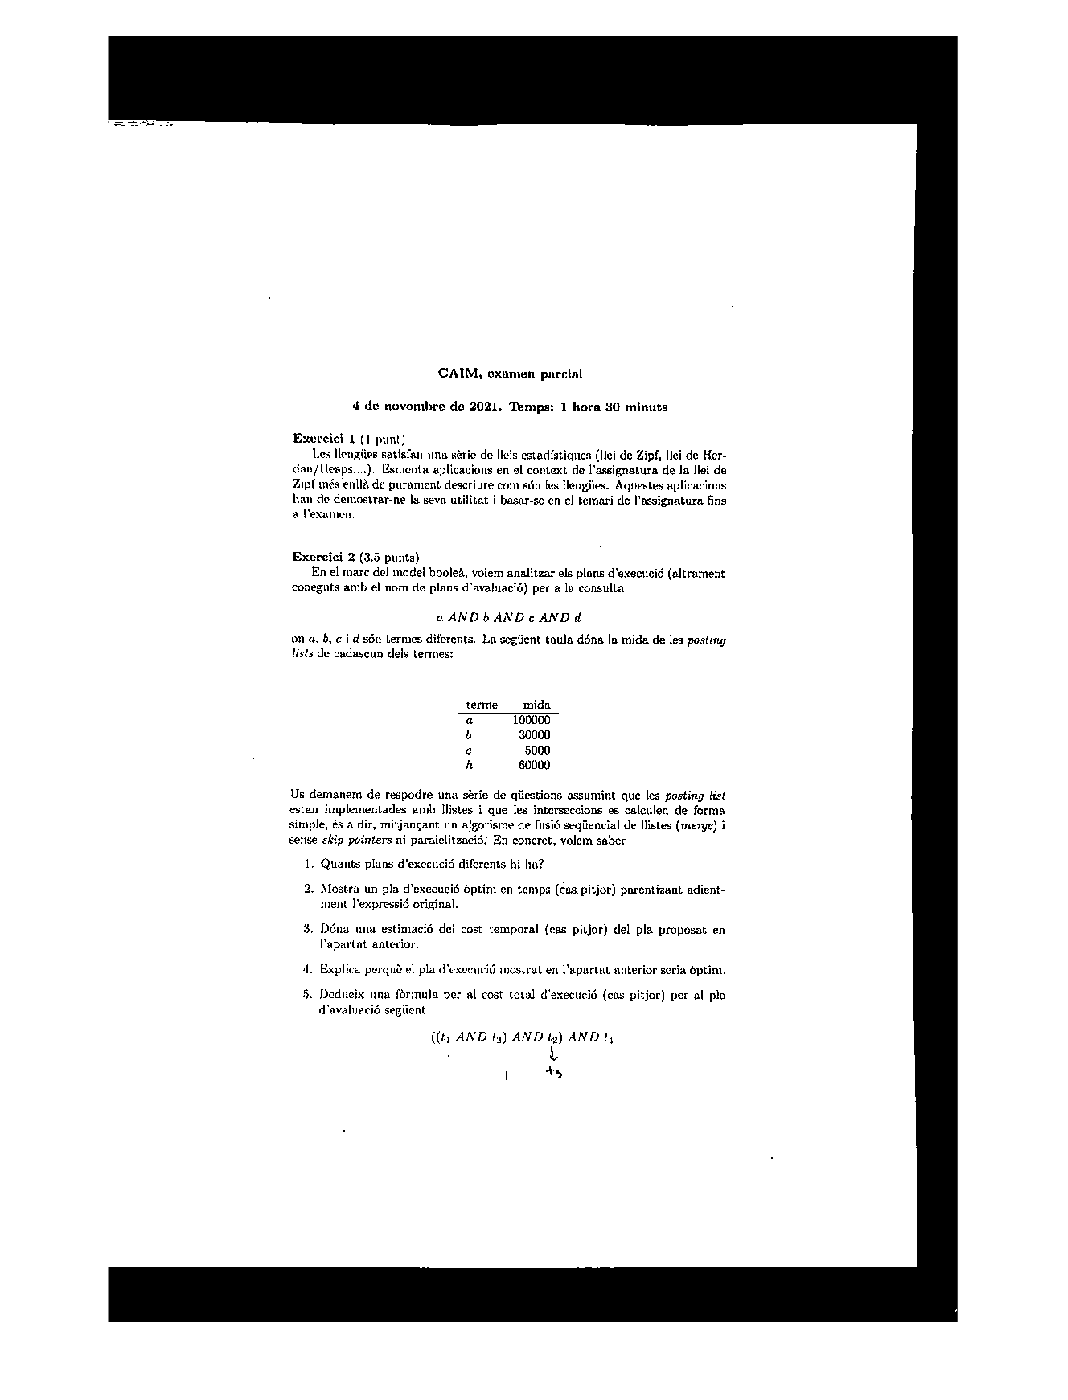

BW = I > 145;
imshow(BW);

blanc = nnz(BW)/numel(BW)

blanc = 0.8223

Amb l'histograma veiem dues seccions clarament definides, amb un llindar de 145 ens dóna un resultat prou bo per una binarització global, amb un 82.2% de blanc.

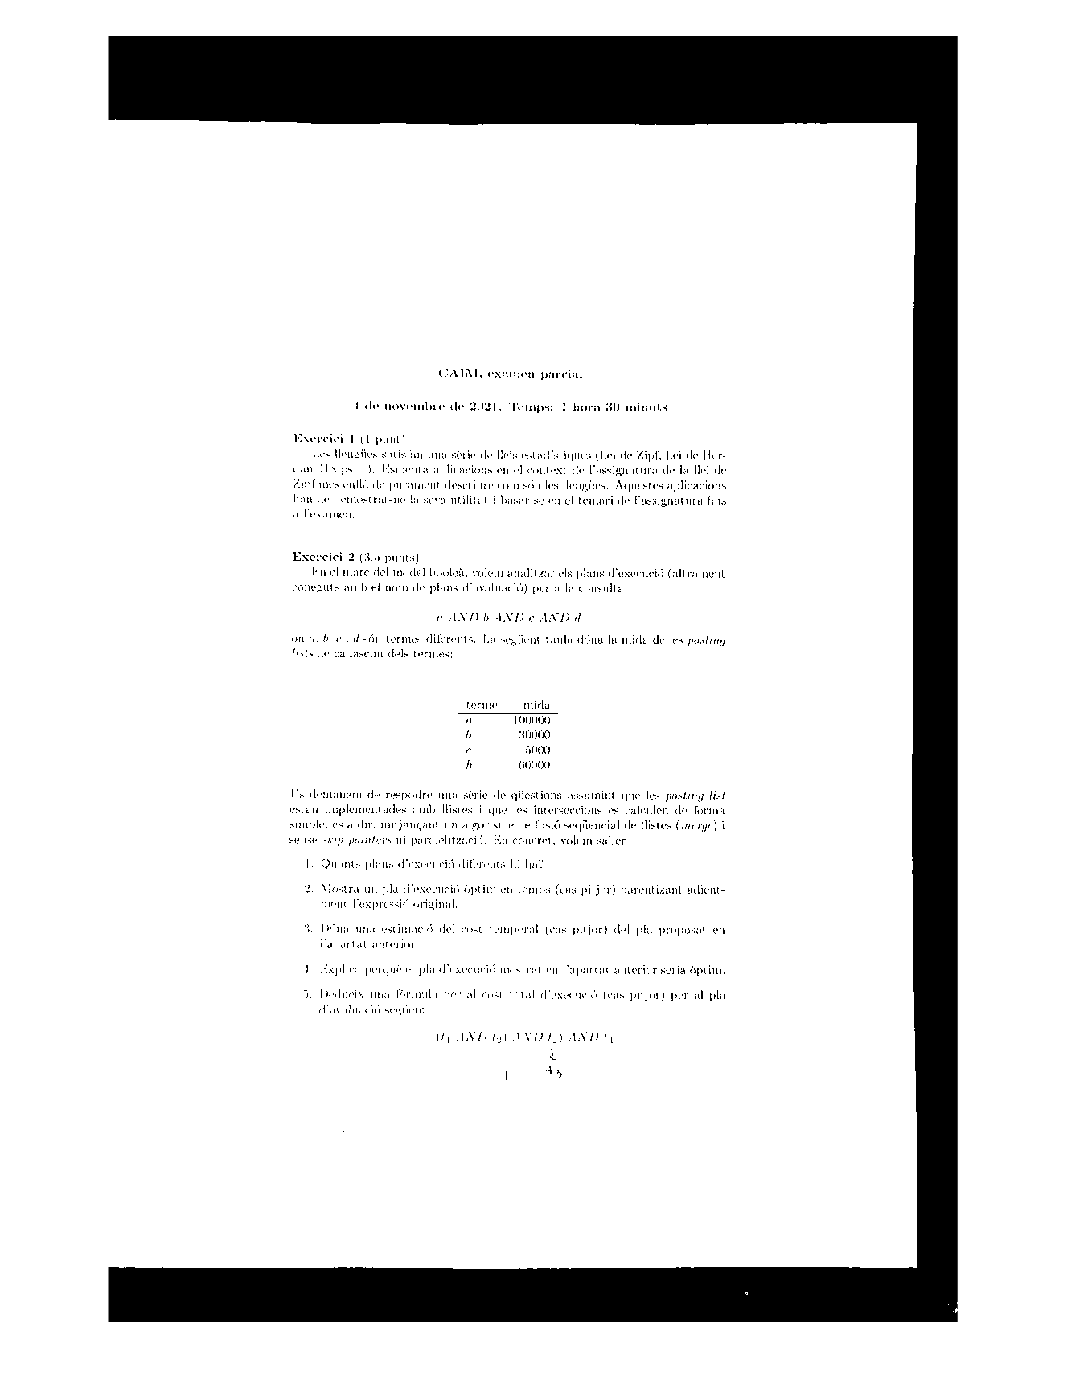


T = otsuthresh(h);
BWO = I > (T*255);
imshow(BWO);

blanc = nnz(BWO)/numel(BWO)

blanc = 0.8342

Provem també de fer servir l'Otsu thresholding, però el resultat obtingut és pitjor que el del llindar de 145 (hi ha caràcters que han perdut connectivitat o han desaparegut). Amb aquesta tècnica tenim un 83.4% de blanc.

**3.** Retalleu la imatge original amb els marges que es poden detectar de la imatge binaritzada globalment. Opcionalment podeu transformar la imatge obtinguda per rectificar petites rotacions del document en relació a la imatge (imrotate).

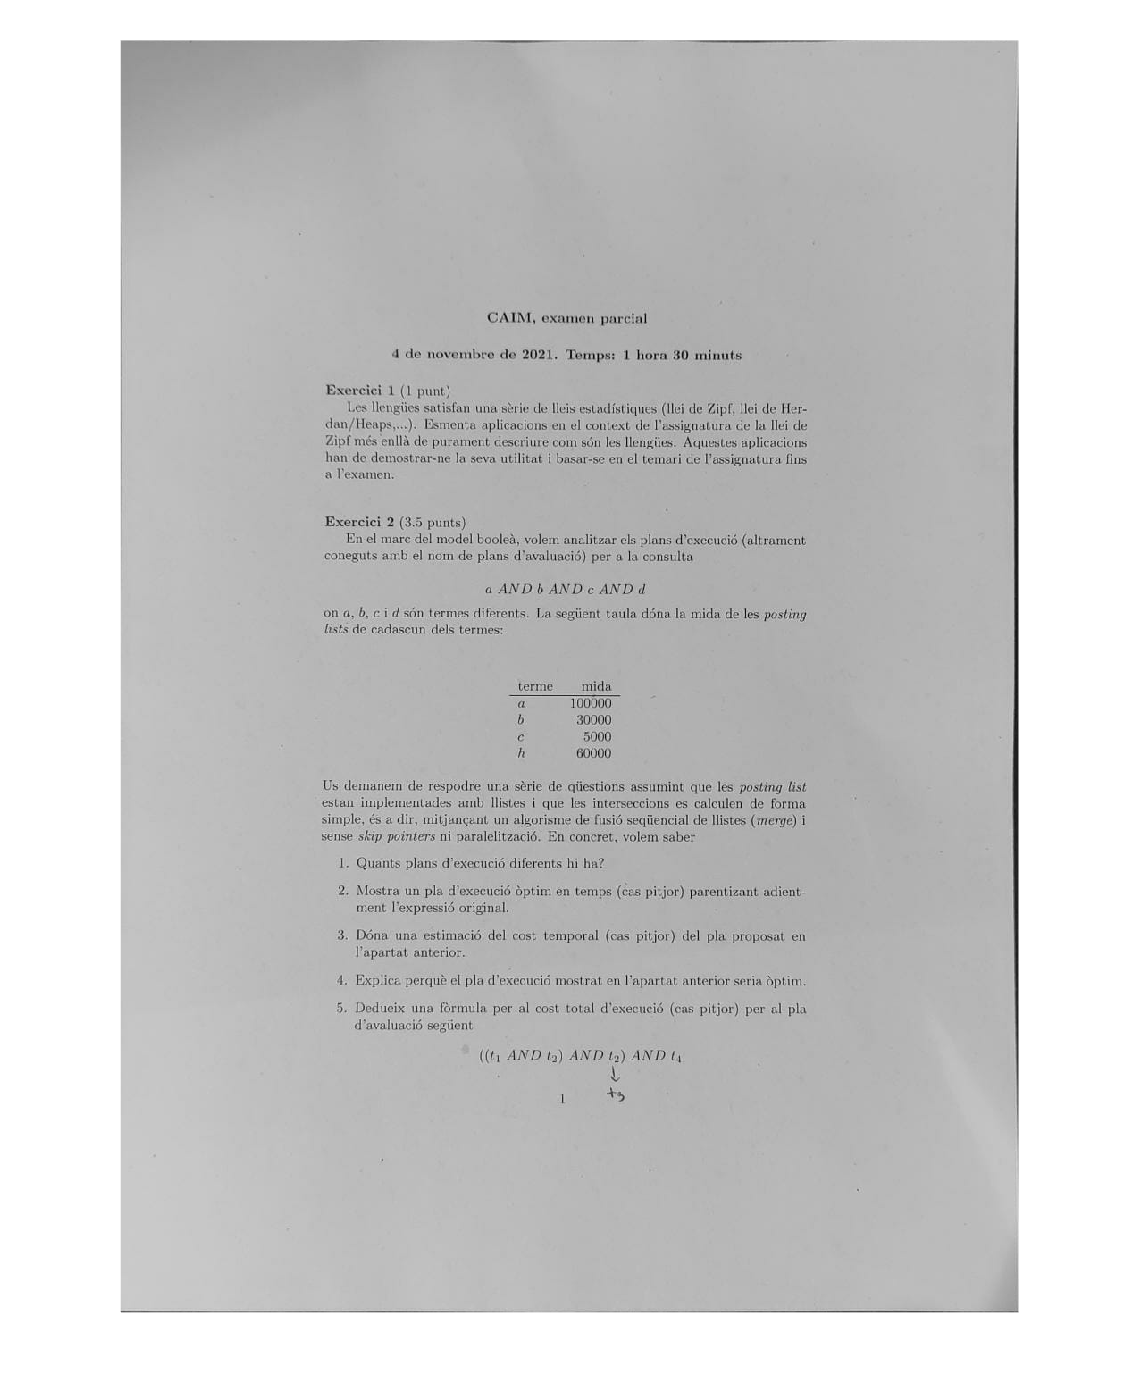

BW = I > 170;
[rows,cols] = find(BW);
rowmin = min(rows);
rowmax = max(rows);
colmin = min(cols);
colmax = max(cols);

IR = I(rowmin:rowmax,colmin:colmax);
imshow(IR);

Fem servir la funció find (que ens dóna els índexs amb elements diferents de zero) sobre la imatge binaritzada per trobar la primera i última fila amb algun element blanc i la primera i última columna amb elements blancs, amb aquestes files i columnes màximes i mínimes i agafant la imatge original (I), traiem les  bandes negres i ens quedem només amb el paper (IR). Cal destacar que la imatge binaritzada no és la de l'apartat anterior (amb un llindar de 145) perquè amb aquesta imatge hi havia elements blancs a les regions negres externes, això ho hem resolt binaritzant amb un llindar més gran (170). La imatge resultada és el paper sense les regions negres externes per tant, està ben retallat.

4. Binarització local. Utilitzant la funció *colfilt*, implementeu, amb codi propi, una binarització local amb una finestra lliscant [M N] que binaritzi a blanc els píxels que són K nivells de gris superiors que el promig de la finestra. Proveu quins resultats produeix amb finestres ajustades a la binarització del text, de tal manera que N tingui el valor de l’alçada d’una o dos línies de text completes (amb l’espai entre línies inclòs) i M tingui la mida d’un caràcter (amb la separació entre caràcters inclosa).

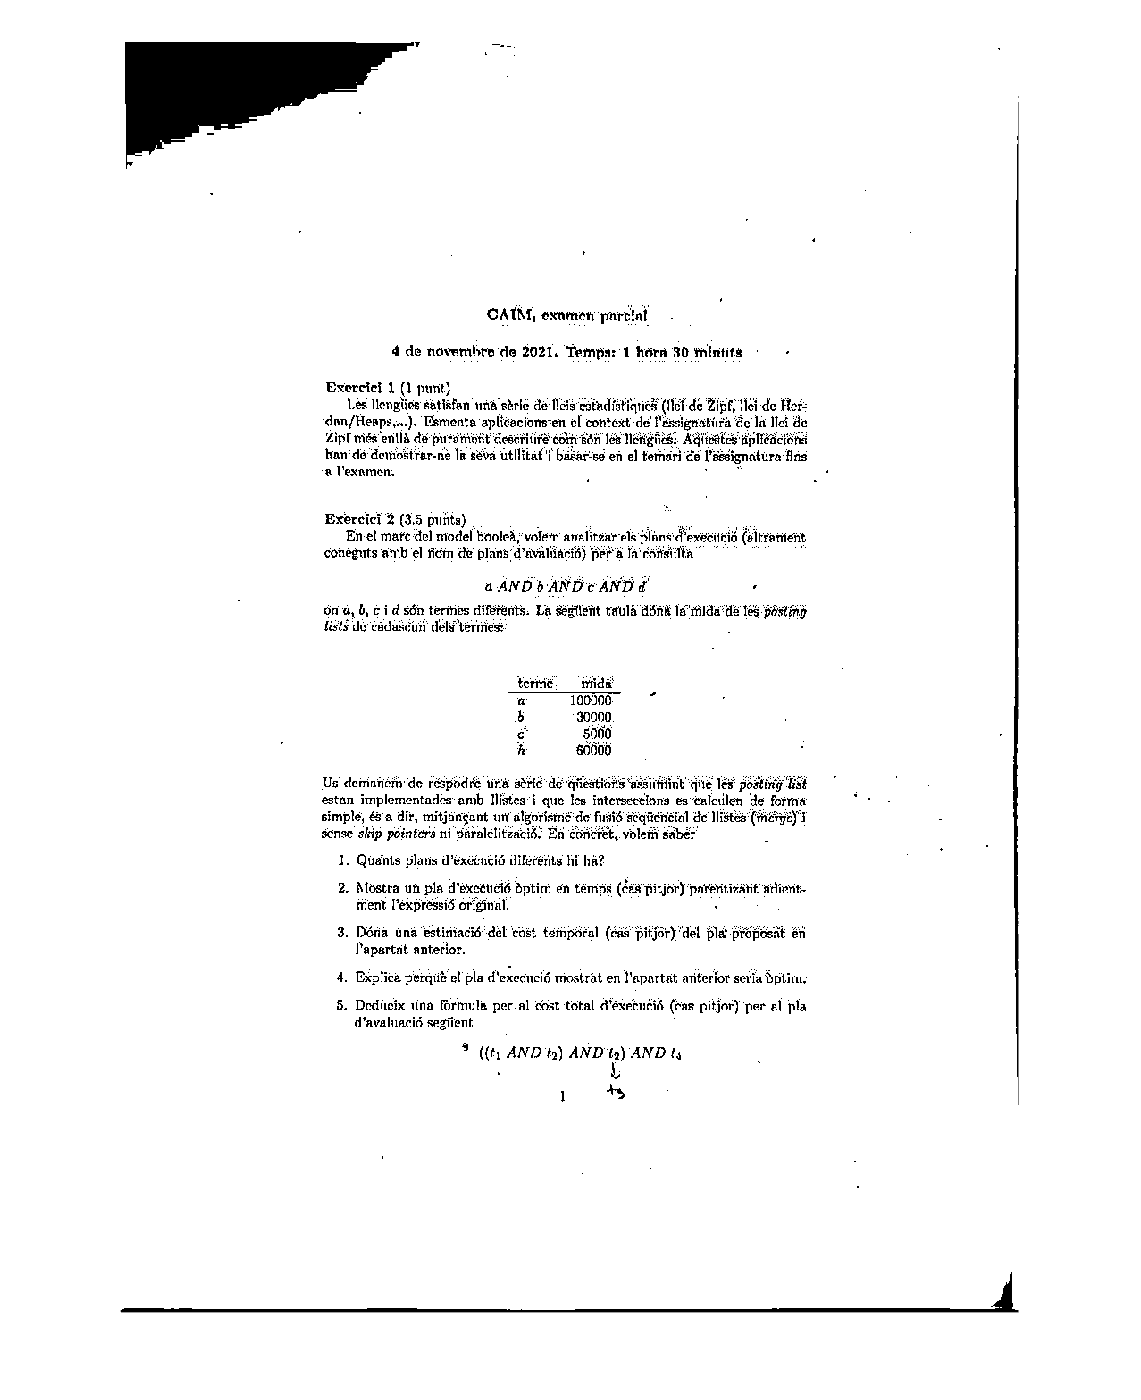

M = 6;
N = 14;
BWL = colfilt(IR,[M N],'sliding',@myfunction);
imshow(BWL);

Binaritzem localment fent servir colfilt amb una finestra lliscant de [6 14] i una K de 0. Aquests paràmetres han sigut provats experimentalment i son els que donen millor resultat.Binaritzem localment fent servir colfilt amb una finestra lliscant de [6 14] i una K de 0. Aquests paràmetres han sigut provats experimentalment i són els que donen millor resultat. Tot i això, la imatge té molts elements negres petits que no són caràcters. Tot i això, la imatge te molts elements negres petits que no son caràcters.

5. Compteu si el número de lletres/signes que us apareix al aplicar la funció (bwconncomp) és més o menys el correcte. Elimineu les taquetes petites.

%eliminar taques petites
%bwconncomp
BWI = 1-BWL;
C =bwconncomp(BWI)

C = struct with fields:
    Connectivity: 8
       ImageSize: [1424 1005]
      NumObjects: 3407
    PixelIdxList: {1×3407 cell}


area = regionprops(C, 'Area');
caracters = 0;
for i = 1 : length(area)
    if(area(i).Area > 6)
       caracters = caracters +1; 
    else
       BWI(C.PixelIdxList{i}) = 0;
    end
end
caracters % filtrem els elements amb area molt petita

caracters = 1229

          % el nombre de caracters es proper a aquest nombre
%imshow(BWI);
imshow(1-BWI);

Per trobar els caràcters de la imatge em fet servir la funció bwconncomp amb la imatge inversa de l'apartat anterior (1-BWL) per tal de que detecti les components conexes negres. De les 3407 components, moltes eren petits elements negres i no caràcters, per tal d'eliminarlos hem tret tots els elements amb area mes petita qué 6 (cap caràcter es més petit que 6). No hem fet un close perqué hauria malfet els caràcters també.

El resultat son 1229 components conexes de les quals gran part son caràcters.

6. Enquadreu amb vermell cada símbol detectat. El resultat és el correcte? Per enquadrar els símbols detectats podeu utilitzar el següent codi: 

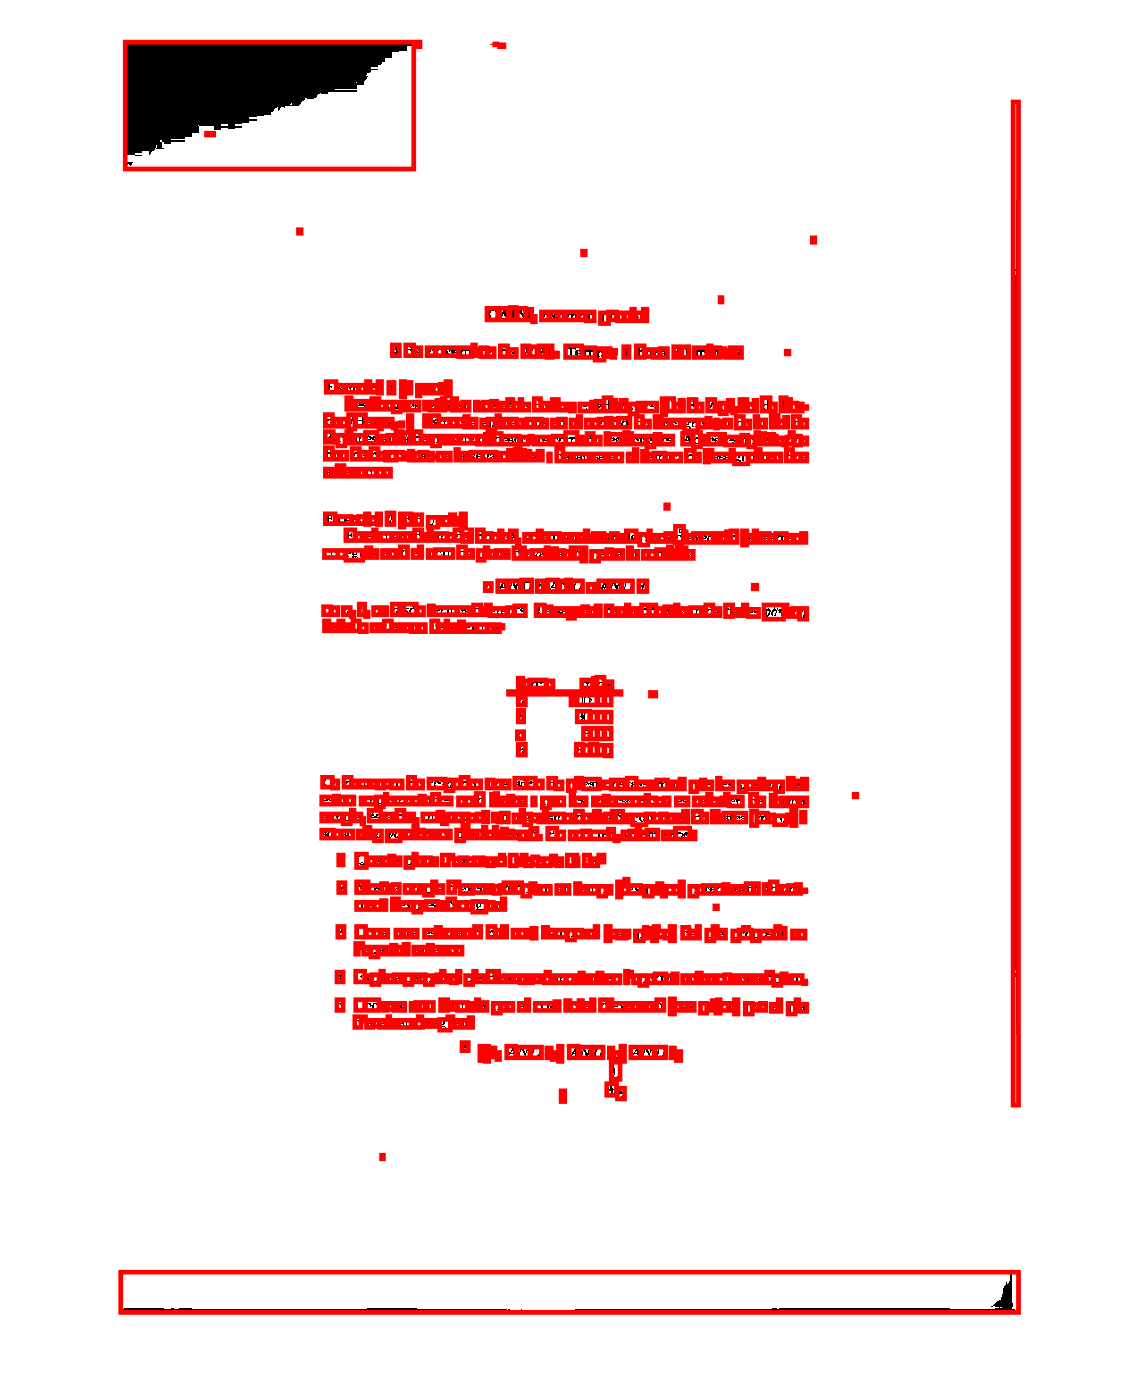

labeledImage = bwconncomp(BWI);
measurements = regionprops(labeledImage,'BoundingBox');
%area = regionprops(labeledImage,'Area');
for k = 1 : length(measurements)
   
   thisBB = measurements(k).BoundingBox;
   rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
   'EdgeColor','r','LineWidth',2 )
end

El resultat és correcte (un altre cop hem aplicat bwconncomp sobre la imatge inversa per detectar components negres), podem veure  que els caràcters són perfectament enquadrats (a més hi ha quadrats que  no encerclen caràcters, però són pocs).

Repetim el mateix amb un altre document.

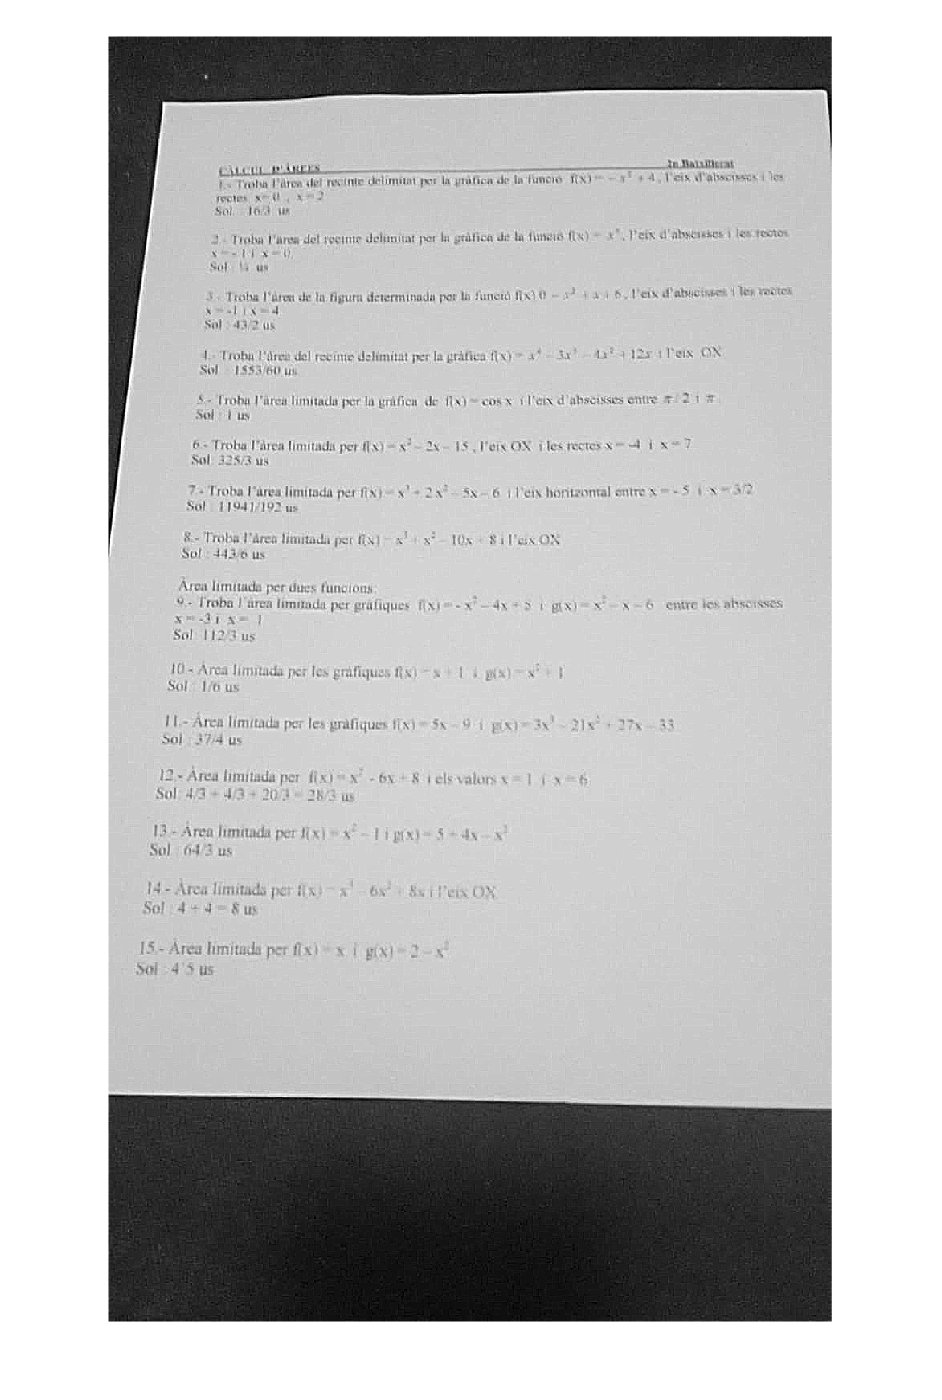

I = rgb2gray((imread("img3.jpg")));
imshow(I);

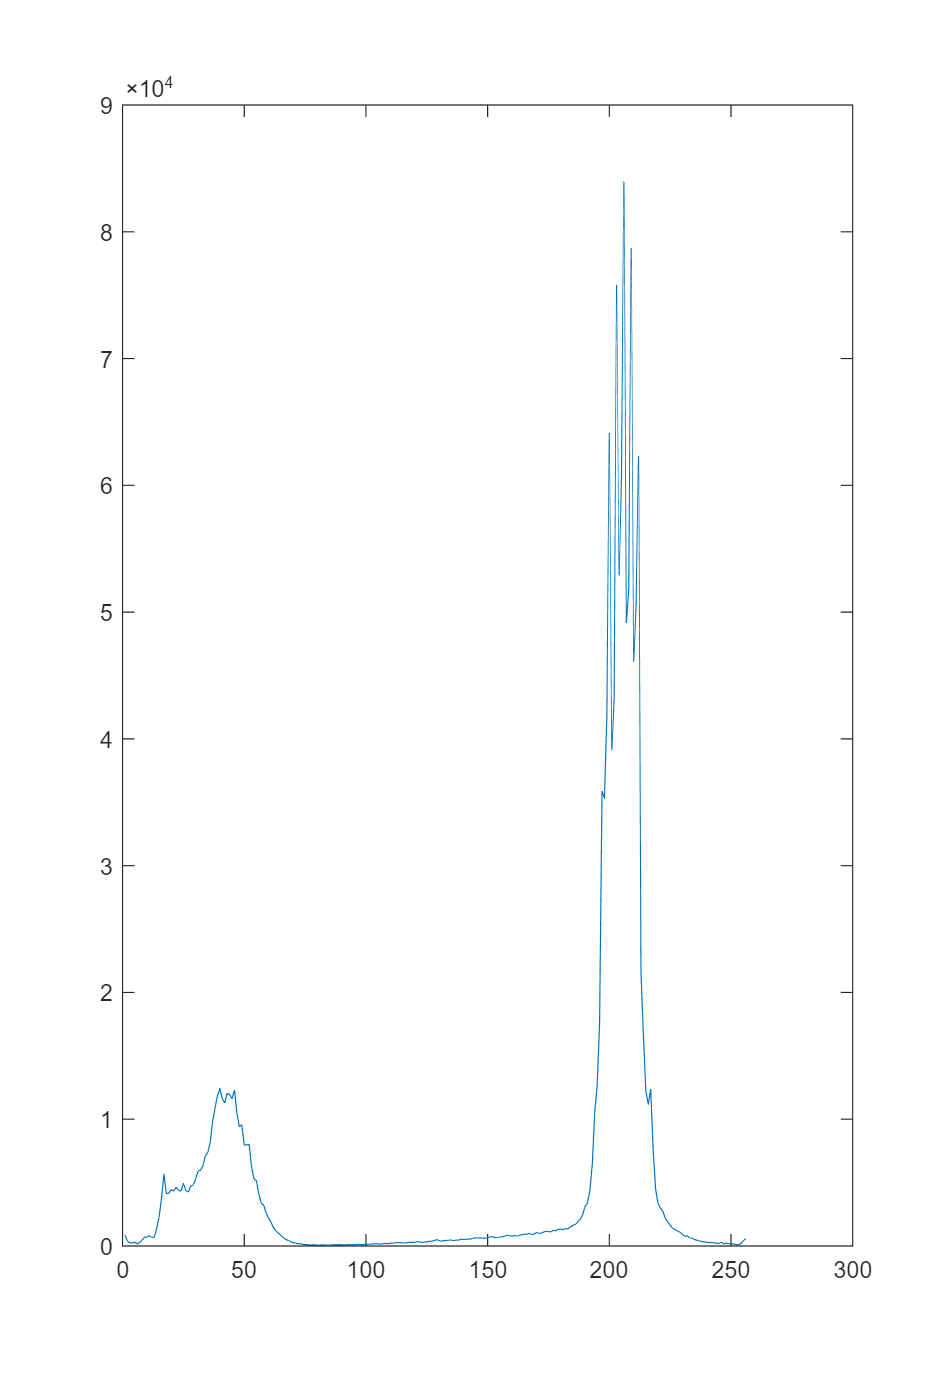


h = imhist(I); plot(h);

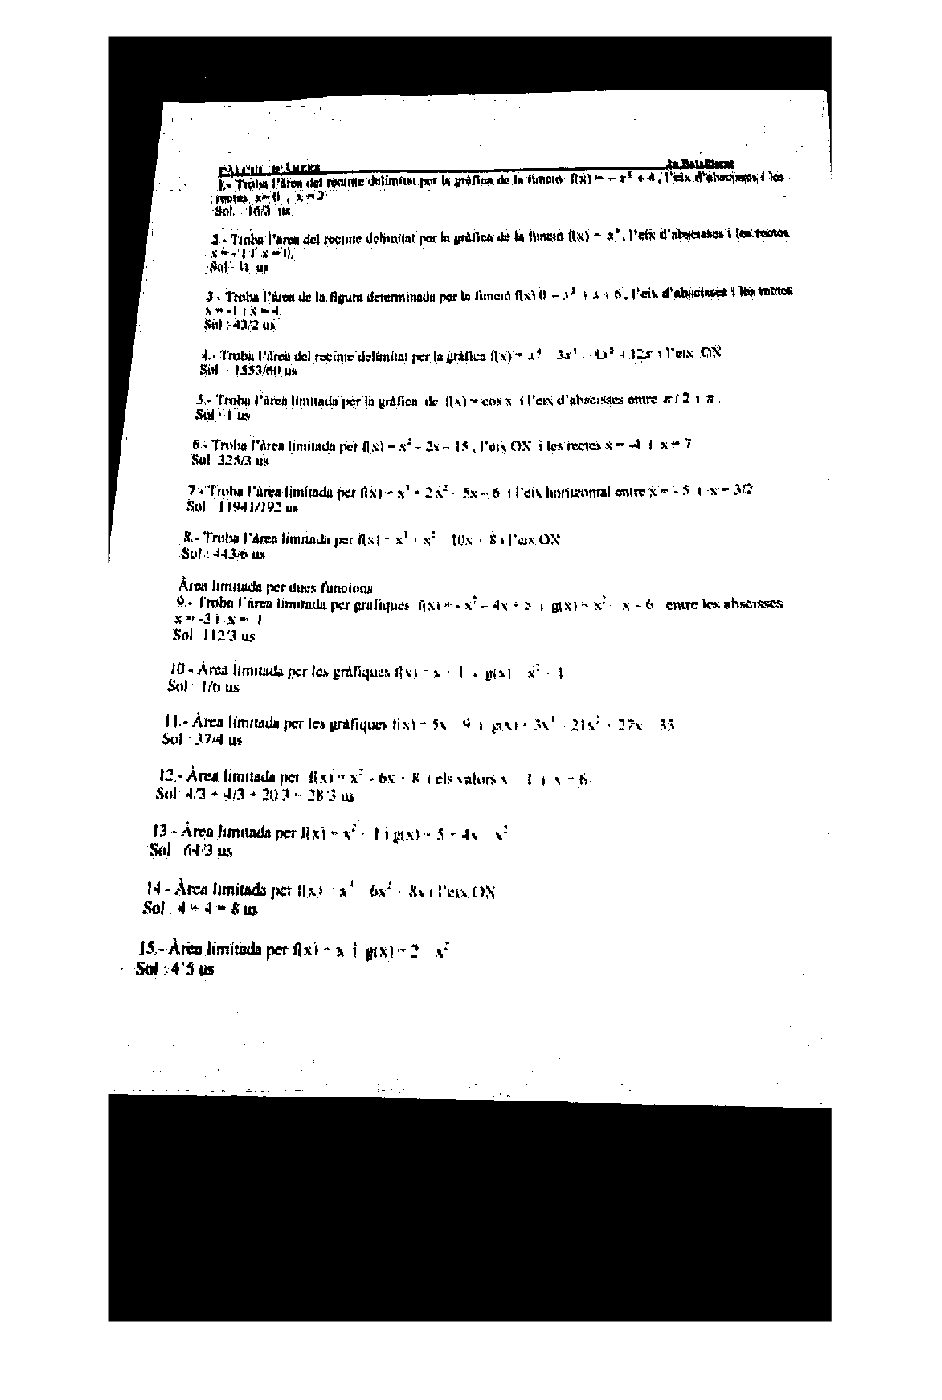

BW = I > 185;
imshow(BW);

blanc = nnz(BW)/numel(BW)

blanc = 0.7305

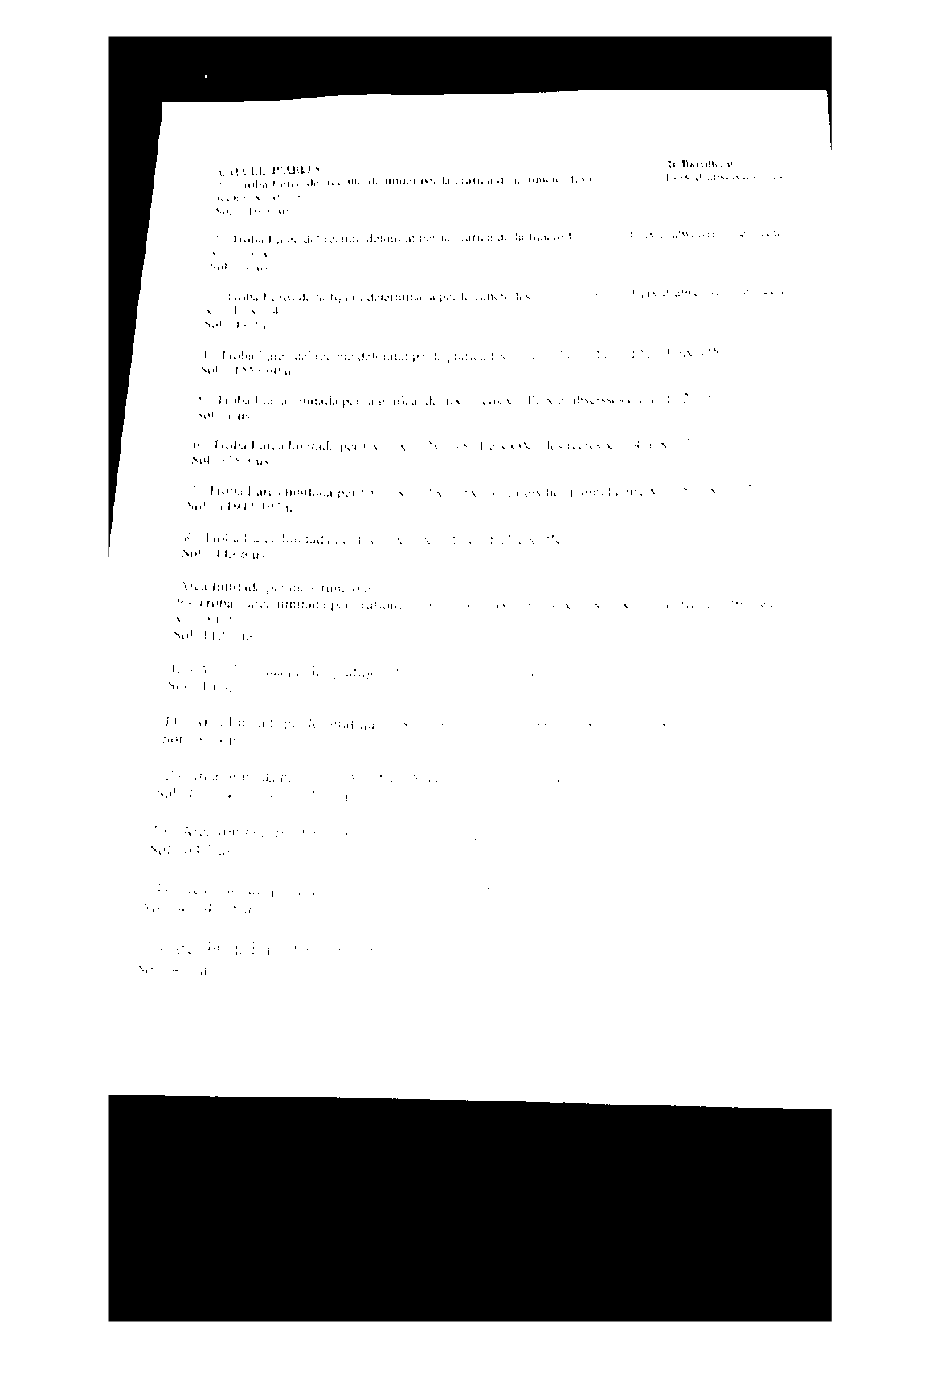


T = otsuthresh(h);
BWO = I > (T*255);
imshow(BWO);

blanc = nnz(BWO)/numel(BWO)

blanc = 0.7656

Passa el mateix, la binarització primera dona millor resultat.

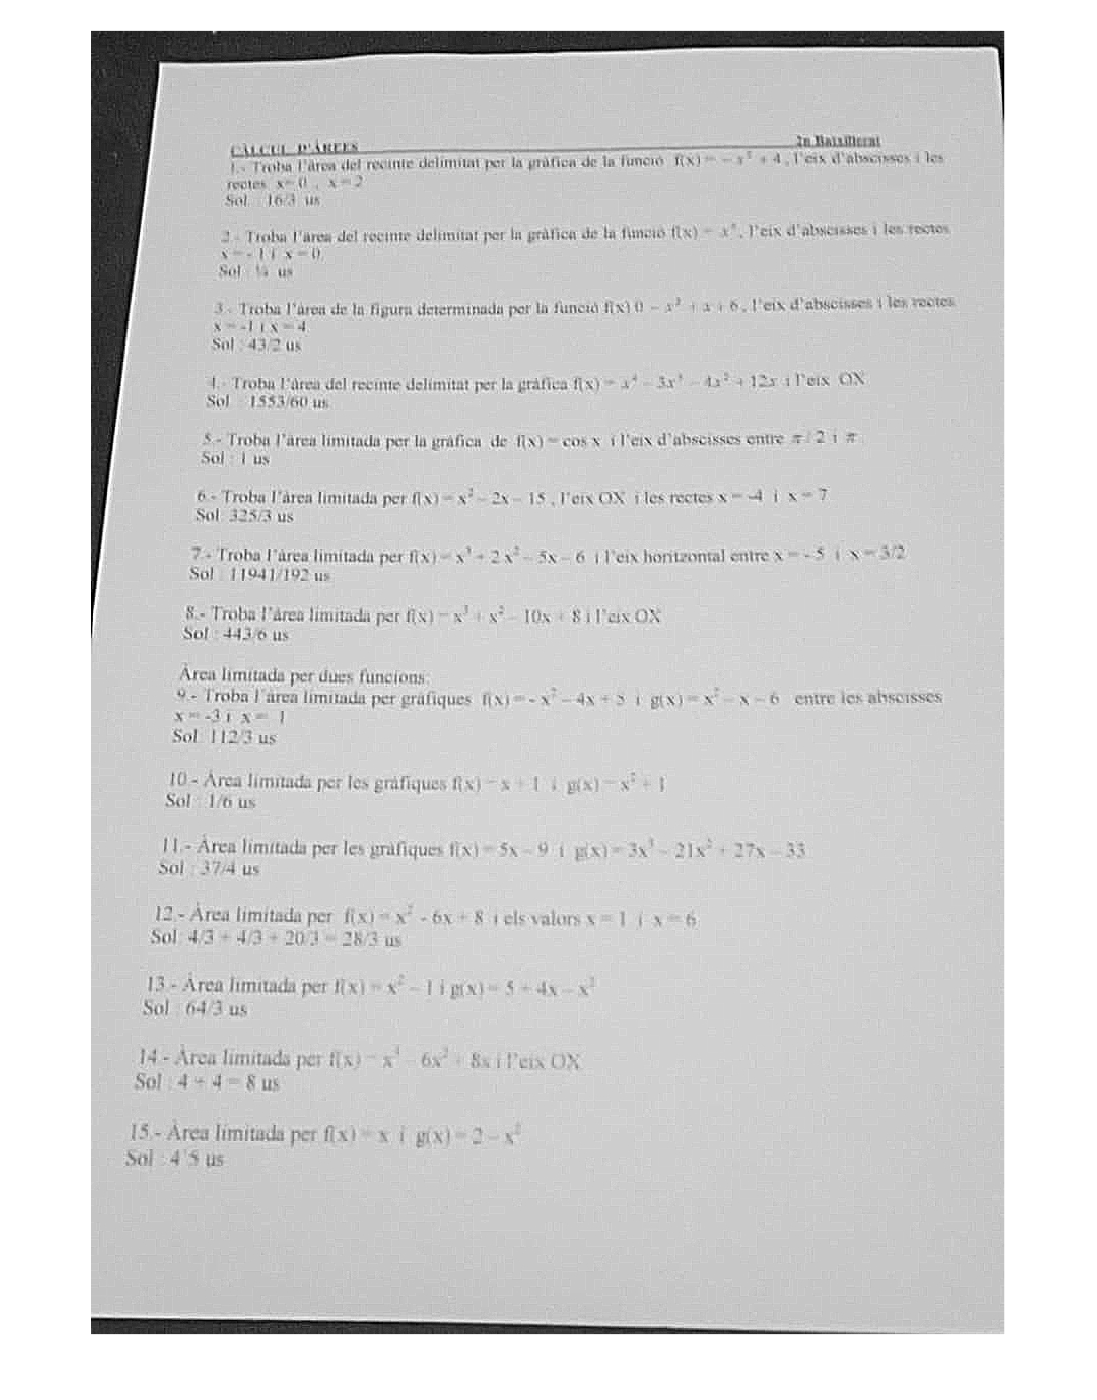


%BW = I > 170; % comentar els punts blancs que molesten per retallar
[rows,cols] = find(BW);
rowmin = min(rows);
rowmax = max(rows);
colmin = min(cols);
colmax = max(cols);

BWR = I(rowmin:rowmax,colmin:colmax);
imshow(BWR);

En aquest cas no cal fer una altra binarització, però cal dir que com el full no està centrat, queden més regions negres externes aquest cop.

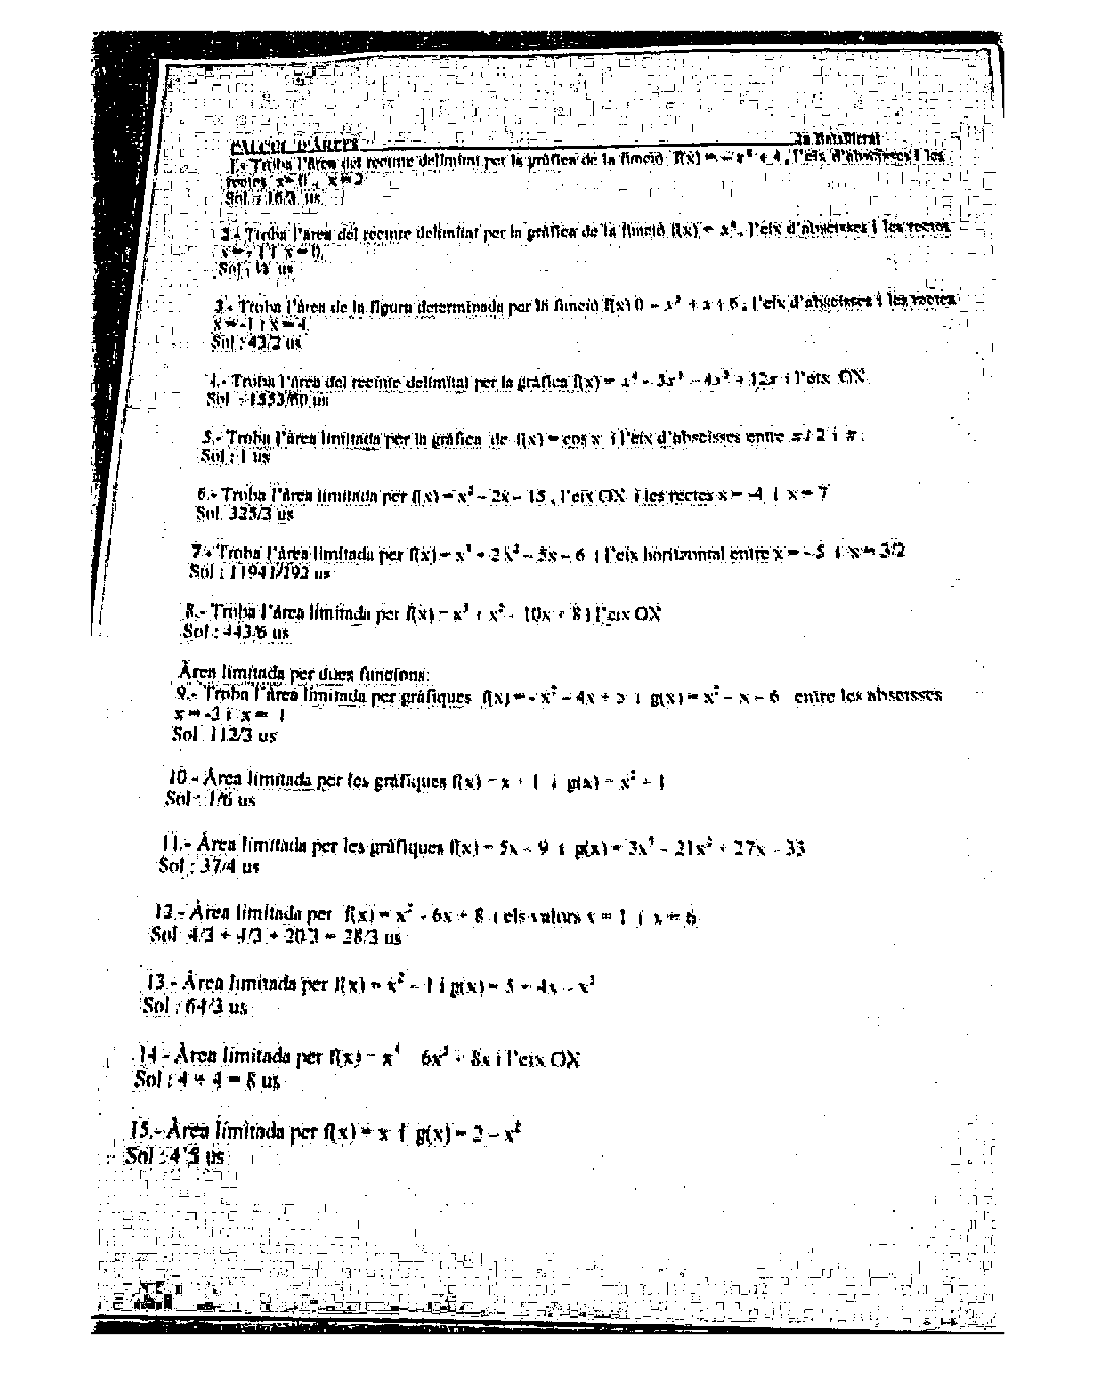


M = 4;
N = 16;
BWL = colfilt(BWR,[M N],'sliding',@myfunction);
imshow(BWL);


BWI = 1-BWL;
C =bwconncomp(BWI)

C = struct with fields:
    Connectivity: 8
       ImageSize: [1284 900]
      NumObjects: 5071
    PixelIdxList: {1×5071 cell}


area = regionprops(C, 'Area');
caracters = 0

caracters = 0

for i = 1 : length(area)
    if(area(i).Area > 15)
       caracters = caracters +1; 
    else
       BWI(C.PixelIdxList{i}) = 0;
    end
end
caracters % filtrem els elements amb area molt petita

caracters = 1072

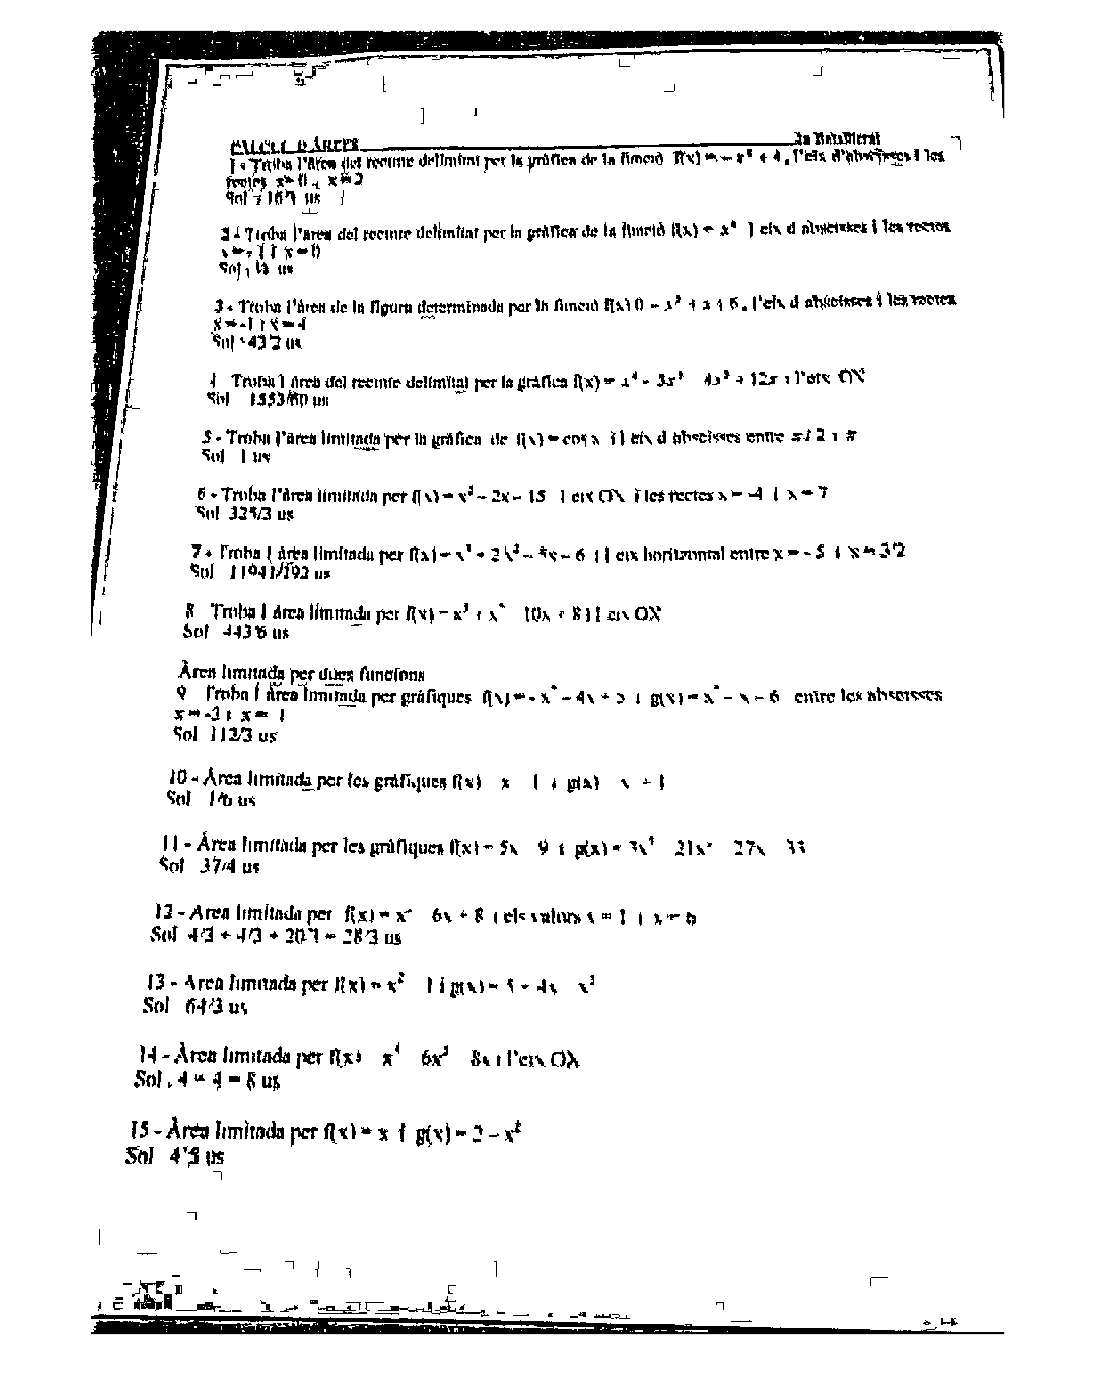

          % el nombre de caracters es proper a aquest nombre
%imshow(BWI);
imshow(1-BWI);

Tornem a fer colfilt aquest cop amb una finestra de [4 16] i K de 0 altre cop. Ens dóna un bon resultat (millor que el binaritzat global). Passa el mateix que amb l'anterior, hi ha moltes taques negres petites que no són caràcters, aquest cop traiem els elements amb àrea  menor a 15.

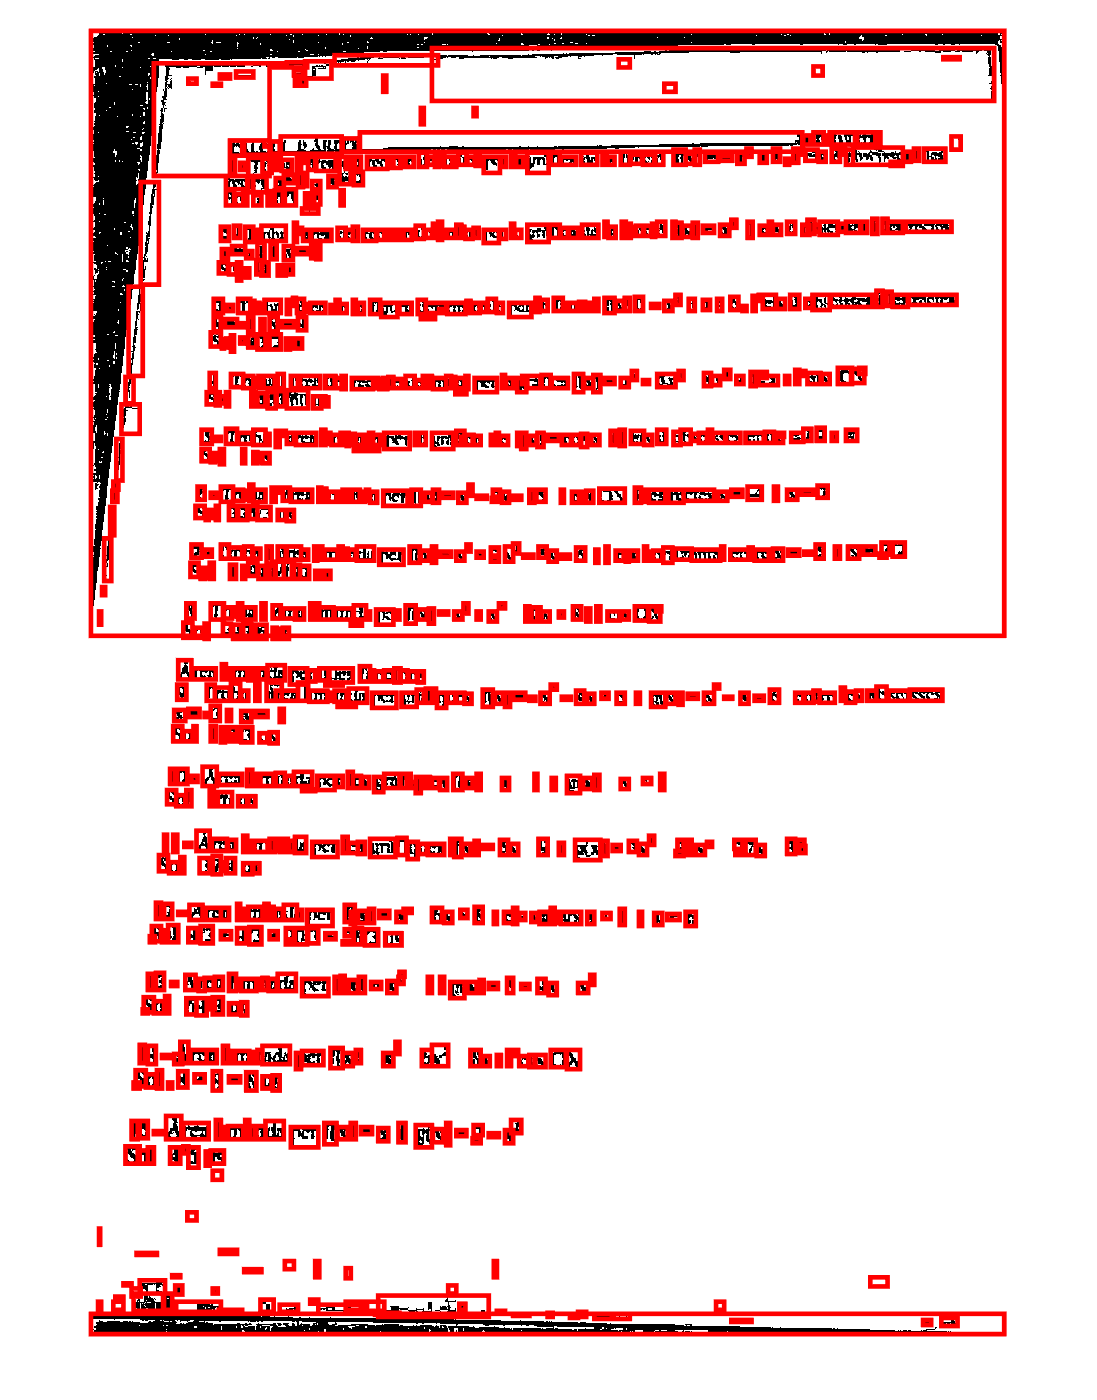

labeledImage = bwconncomp(BWI);
measurements = regionprops(labeledImage,'BoundingBox');
%area = regionprops(labeledImage,'Area');
for k = 1 : length(measurements)
   
   thisBB = measurements(k).BoundingBox;
   rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
   'EdgeColor','r','LineWidth',2 )
end

Tot i fer el test amb un full menys centrat el resultat és similar, tots els caràcters estan enquadrats, i hi ha relativament pocs elements que no són caràcters enquadrats.

function [y] = myfunction(x)
 [f c] = size(x);
 mean = sum(x/f);
 central = x(f/2,:);
 y = central > (mean);
end